# Create Timetable from Spreadsheet File and Format Input Data

Create a timetable from a spreadsheet file and format the input data. For instance, create a timetable from the file `quarterlyFinances1999To2019.csv`, specify the start date of the time stamps and the time between each of them, and remove the "$" symbol from the data.

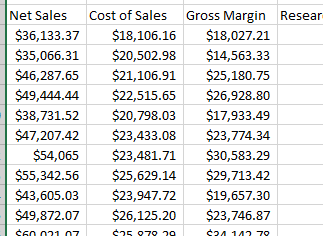

Read the data in the file `quarterlyFinances1999To2019.csv` as a timetable. Specify the length of time between consecutive row times to be one calendar quarter, beginning on the date January 1, 1999. Set `'VariableNamingRule'` to `preserve` to preserve the whitespace in the variable names, and set `'TrimNonNumeric'` to `true` to remove the "$" symbol before the numeric values in the data.

TT = readtimetable("quarterlyFinances1999To2019.csv","TimeStep", calquarters(1),"StartTime", datetime(1999, 1, 1),...
    "VariableNamingRule", "preserve", "TrimNonNumeric", true);

Display a summary of the data.

summary(TT)

*Copyright 2020 The MathWorks, Inc.*